fid = fopen('C:\Users\HP\Desktop\上课\图像处理代码\For_Students(2)\For Students\rodin.raw', 'rb');
% 读取图像数据
I = fread(fid,[348,inf],'uint8')'

I =    103   129   131   119   113   115   122   106   117   117   126   134   131   119   118   126   132   126   122   123   127   128   121   115   118   118   117   118   118   118   117   117   110   123   128   122   122   127   106    84    52    43    47    79    90   103   128   108   102    74
   121    96    89   119   133   117   121   133   138   122   112   112   117   117   121   124   115   119   122   118   111   111   116   122   116   116   115   113   113   113   113   113   112   118   122   115   111   119   119   122     0    20    28    71   111   142   121   123   122    85
   127    47     1    44    99   110   106   113   107   108   118   127   131   122   111   105   138   136   131   121   112   112   119   126   123   123   123   122   121   121   119   119   116   117   123   119   113   117   132   155    69    80    58    33    54    79    12    44    69    43
   244   244   225   145    59    26    43    79   115   119   124   119   113   111   121   

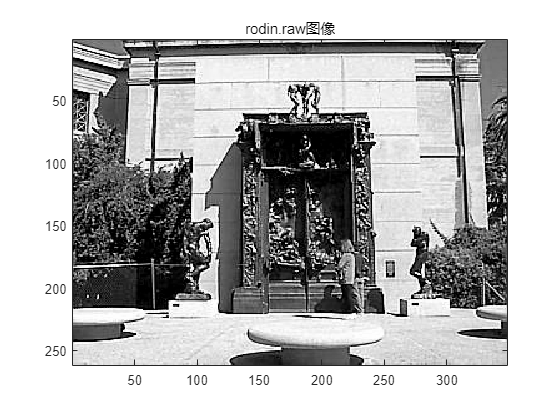

%使用imagesc和axis命令显示图像
figure;
imagesc(I); 
colormap gray;
axis image;
title('rodin.raw图像');

%记录图像的大小
imageSize = size(I);
disp(['图像的大小为: ', num2str(imageSize(1)), ' x ', num2str(imageSize(2))]);

图像的大小为: 261 x 348


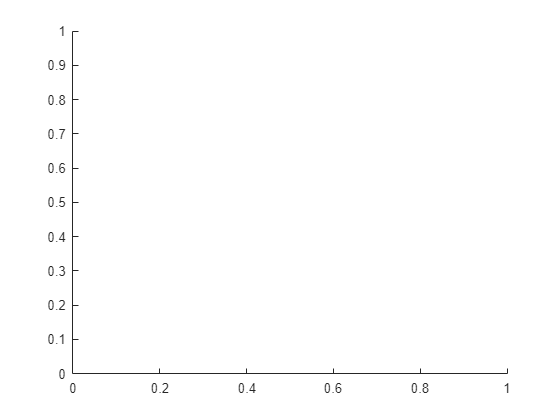

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5
% 对于放大因子为2、3和4
factors = [2, 3, 4];

for scale = factors
    % 初始化放大后的图像
    [rows, cols] = size(I);
    newRows = rows * scale;
    newCols = cols * scale;
    scaledImage = zeros(newRows, newCols, 'uint8');

    % 在已知数据点之间插入零行和零列
    for r = 1:rows
        for c = 1:cols
            scaledImage((r-1)*scale+1, (c-1)*scale+1) = I(r, c);
        end
    end
    
    % 显示放大后的图像
    figure;
    imagesc(scaledImage);
    colormap gray;
    title(['放大因子为 ', num2str(scale)]);
    axis image;

    % 使用缩放功能查看完整分辨率的像素
end

fid2 = fopen('C:\Users\HP\Desktop\上课\图像处理代码\For_Students(2)\For Students\rodin.raw', 'rb');
% 读取图像数据
J = fread(fid2,[348,inf],'uint8')'
figure;
imagesc(J); 
colormap gray;
axis image;
title('rodin.raw图像');
% rotated_img = imrotate(J, 60);  
rotated_img = rotate2D(J, 10);
imagesc(rotated_img); 
colormap gray;
axis image;


fid1 = fopen('C:\Users\HP\Desktop\上课\图像处理代码\For_Students(2)\For Students\lab4prob3data1', 'rb');
fid2 = fopen('C:\Users\HP\Desktop\上课\图像处理代码\For_Students(2)\For Students\lab4prob3data2', 'rb');

% I = fread(fid1,[640,inf],'uint8')'
% figure;
% imagesc(I); 
% colormap gray;
% axis image;
L = 640
img1 = fread(fid1, [L, inf], 'uint8')';
img2 = fread(fid2, [L, inf], 'uint8')';

fclose(fid1);
fclose(fid2);

% 显示两个图像
figure;
subplot(1,2,1); 
imagesc(img1); colormap gray; title('lab4prob3data1 图像');
subplot(1,2,2); 
imagesc(img2); colormap gray; title('lab4prob3data2 图像');

img_diff = double(img1) - double(img2);

figure;
imagesc(img_diff); colormap gray; 
title('图像差异');


fid = fopen('C:\Users\HP\Desktop\上课\图像处理代码\For_Students(2)\For Students\lab4prob4data', 'rb');

% I = fread(fid,[640,inf],'uint8')'
% figure;
% imagesc(I); 
% colormap gray;
% axis image;
L = 640
img = fread(fid, [L, inf], 'uint8')';
fclose(fid);

% 显示图像
figure;
imagesc(img); colormap gray; 
title('lab4prob4data 图像');

% ii. 计算图像的负片
img_negative = 255 - img;

% 显示负片图像
figure;
imagesc(img_negative); colormap gray; 
title('图像的负片');

image_path = 'E:\A-Secret- Bases\值得记住\南科大的玫瑰色\微信图片_20220907210116.jpg';
img = imread(image_path)%1600 2399
% 转换为灰度图像
img_gray = rgb2gray(img);
imshow(img_gray);
axis image;
% ii. 分割原始图像的一部分
x_start = 500; 
y_start = 100; 
width =500; 
height = 800; 
subset_img = img_gray(y_start:y_start+height-1, x_start:x_start+width-1);
imshow(subset_img);

% iv. 使用你刚写的函数插入你切出的图像片段 (iii)
result1 = overlay_images(img_gray, subset_img, 100, 400); 
result2 = overlay_images(img_gray, subset_img, 200, 500);
result3 = overlay_images(img_gray, subset_img,300, 600); 

imshow(result1);
imshow(result2);
imshow(result3);

%v
blended_result = blend_images(img_gray, subset_img, 600, 600, 0.2); 
imshow(blended_result);

fid = fopen('C:\Users\HP\Desktop\上课\图像处理代码\For_Students(2)\For Students\lab4prob6data', 'rb');
I = fread(fid,[582,inf],'uint8')'

I =     89   166   106   149     0     0     2   128     0     0     1   224     0     0     0     8     0     4   176     0     0     0     0     1     0     0     0     1     0     0     3     0     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17
    83    37    83    95    37    37    37    37    83    37    37    93    37    37    83    37    37    83    37    83    59    83    37    37    86    37    43    95    86    95    43    95    95    95    86    95    95    86    59    95    86    37    43    95    95    43    93    43    95    37
    37    56    37    37    93    37    37    37    56    37    37    37    37    37    43    93    37    37    86    56    83    37    83    95    83    95    37    86    59    86    95    86    86    95    95    86    95    37    95    86    37    95    95    37    86    95    95    37    86    95
    83    37    83    37    37    37    83    37    37    83    37    93    37    37    83   

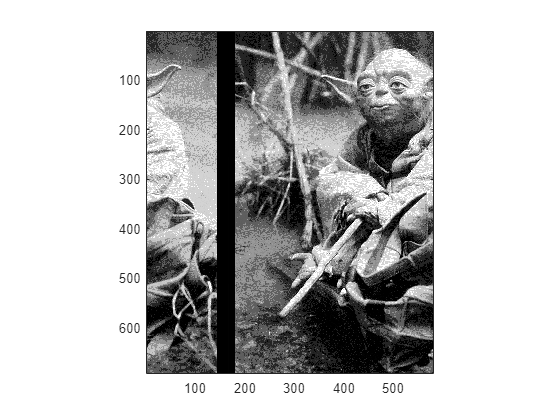

figure;
%plot(I)
imagesc(I)
colormap("gray")
axis image;

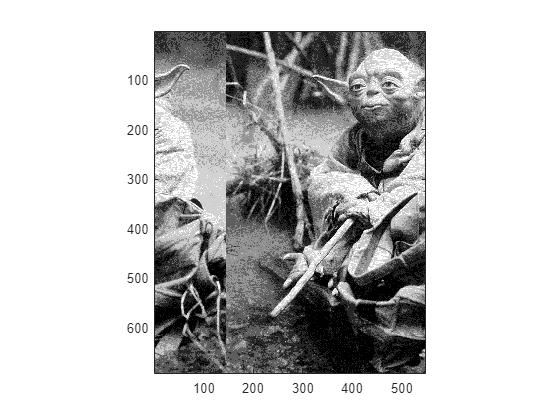

% 计算每列的平均值
avgValues = mean(I, 1);
% 使用一个阈值来找到较暗的列
threshold = 50; % 你可以根据需要调整这个值
darkCols = avgValues < threshold;
% 保留那些平均值高于阈值的列
I_cleaned = I(:, ~darkCols);
% 显示清理后的图像
figure;
imagesc(I_cleaned);
colormap("gray");
axis image;


% % 找到所有完全为0的列
% blackCols = all(I == 0, 1);
% % 保留那些不是完全为0的列
% I_cleaned = I(:, ~blackCols);
% % 显示清理后的图像
% figure;
% imagesc(I_cleaned);
% colormap("gray");
% axis image;



function rotated_img = rotate2D(img, theta) %question 2 
    % theta是旋转角度，以度数为单位

    % 获取图像的行和列
    [rows, cols] = size(img);

    % 将角度转换为弧度
    theta_rad = deg2rad(theta);

    % 创建旋转矩阵
    R = [cos(theta_rad), -sin(theta_rad); 
         sin(theta_rad), cos(theta_rad)];

    % 输出图像初始化为原始图像的大小
    rotated_img = zeros(rows, cols);

    % 计算旋转后的图像
    for x = 1:cols
        for y = 1:rows
            % 将当前的坐标转换为相对于图像中心的坐标
            x_centered = x - cols/2;
            y_centered = y - rows/2;

            % 使用旋转矩阵旋转这个坐标
            rotated_coords = R * [x_centered; y_centered];

            % 转换回原始坐标系统
            x_rot = round(rotated_coords(1) + cols/2);
            y_rot = round(rotated_coords(2) + rows/2);

            % 检查旋转后的坐标是否在图像范围内
            if x_rot >= 1 && x_rot <= cols && y_rot >= 1 && y_rot <= rows
                rotated_img(y, x) = img(y_rot, x_rot);
            end
        end
    end
end

function overlaid_img = overlay_images(large_img, small_img, y, x) %5(iii)
    % 在给定坐标上叠加小图像到大图像
    [h, w] = size(small_img);
    large_img(y:y+h-1, x:x+w-1) = small_img;
    overlaid_img = large_img;
end

% v.
function blended_img = blend_images(large_img, small_img, y, x, alpha)
    [h, w] = size(small_img);
    for i = 1:h
        for j = 1:w
            large_img(y+i-1, x+j-1) = alpha*small_img(i,j) + (1-alpha)*large_img(y+i-1, x+j-1);
        end
    end
    blended_img = large_img;
end


